
                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality


     0          3         91323.5                      1.19e+03


     1          6         91107.3       0.298252           64.2      


     2          9         91106.9     0.00600768         0.0348      


     3         12         91106.9    4.08903e-05       0.000297      


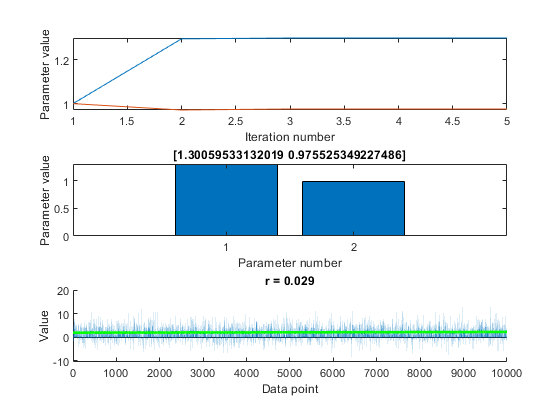


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



a = 1.3; b = 1;
x = linspace(0, 1, 10000);
%noised sample
y = a.^x + b + randn(1, 10000)*2;
options = optimset('Display','iter',...
    'OutputFcn', @(a,b,c) outputfcnplot(a,b,c,1,y));
%initial parameters a and b
params0 = [1 1];
%our model function
modelfun = @(params, x) params(1).^x + params(2);
res = lsqcurvefit(modelfun, params0, x, y, [], [], options);

disp(res);

    1.3006    0.9755

